# FFT for flow meter

filename1 = 'Actual Data/data_from_com1.csv';
filename2 = 'Actual Data/data_from_com2.csv';%flow rate
filename2 = '/Users/DarellCHUA/Downloads/raw_serial_log_3_FLOW.csv';%flow rate
filename2 = '/Users/DarellCHUA/Downloads/data_from_com2_Flow.csv';%flow rate
filename2 = '/Users/darellchua/Documents/LNG Run 1_Flow_cropped.txt';
filename2 = '/Users/darellchua/Documents/LNG Run 2_Flow_cropped.txt';
filename2 = '/Users/darellchua/Documents/LNG Run 3_Flow_cropped.txt';
filename2 = '/Users/darellchua/Documents/LNG Run 4_Flow_cropped.txt';
%filename2 = '/Users/darellchua/Documents/LOX Run 1_Flow_cropped.txt';
%filename2 = '/Users/darellchua/Documents/LOX Run 2_Flow_cropped.txt';
highpassfreq =  0;

% filename1 = '500PSI Actual Data/data_from_com1.csv';
% filename2 = '500PSI Actual Data/data_from_com2.csv';
% highpassfreq =  200;
% %~300 hz

## Pressure

% load the pressure CSV file and plot
opts = detectImportOptions(filename1);
opts.Delimiter = ",";
data = readtable(filename1,opts);

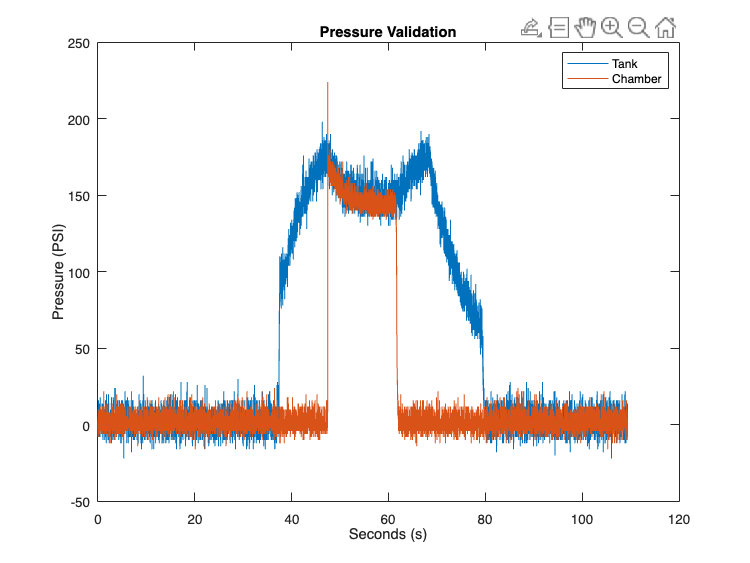


% Extract the 3rd column and 4th (Tank & Chamber)
signal_tank = table2cell(data(:, 3));
% Define a function to convert cell elements to numeric values
convertToNumeric = @(x) str2double(x)*1000/5;
% Use cellfun to apply the conversion function to each element in the cell array
signal_tank = cellfun(convertToNumeric, signal_tank, 'UniformOutput', false);
signal_tank = cell2mat(signal_tank);

% Extract the 3rd column and 4th (Tank & Chamber)
signal = table2cell(data(:, 4));
% Define a function to convert cell elements to numeric values
convertToNumeric = @(x) x*1000/5; %str2double(x);
% Use cellfun to apply the conversion function to each element in the cell array
signal = cellfun(convertToNumeric, signal, 'UniformOutput', false);
signal = cell2mat(signal);


fssignal = table2cell(data(:, 7));
convertToNumeric = @(x) str2double(x);
% Use cellfun to apply the conversion function to each element in the cell array
fssignal = cellfun(convertToNumeric, fssignal, 'UniformOutput', false);
fssignal = cell2mat(fssignal);

fs =  1/mean(fssignal);
plot(fs:fs:length(signal)*fs,signal_tank)
hold on
plot(fs:fs:length(signal)*fs,signal)
hold off
title("Pressure Validation")
legend(["Tank" "Chamber"])
ylabel("Pressure (PSI)")
xlabel("Seconds (s)")

## Flow Rate

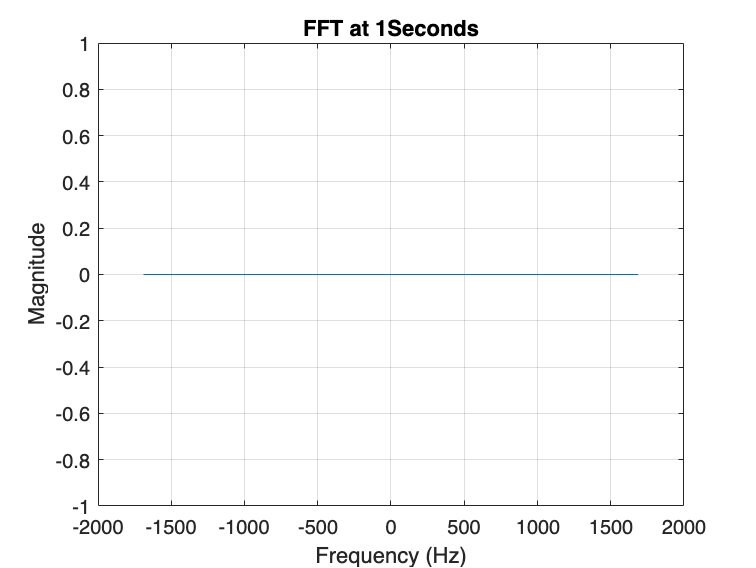

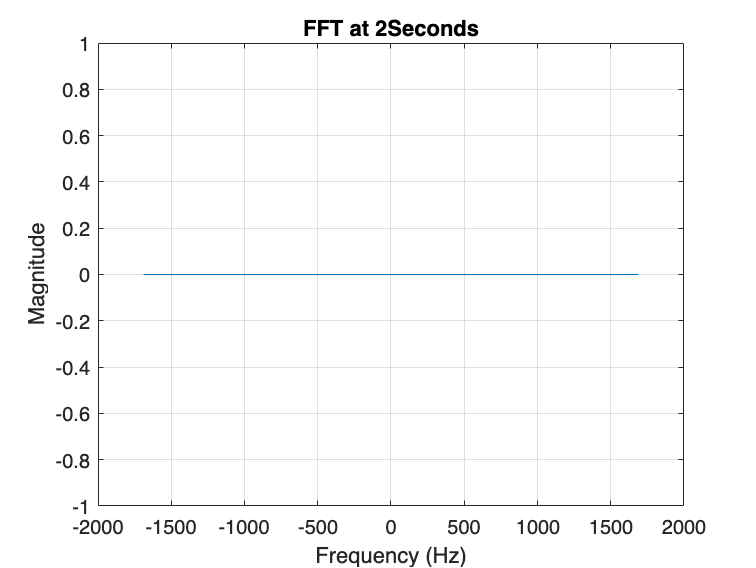

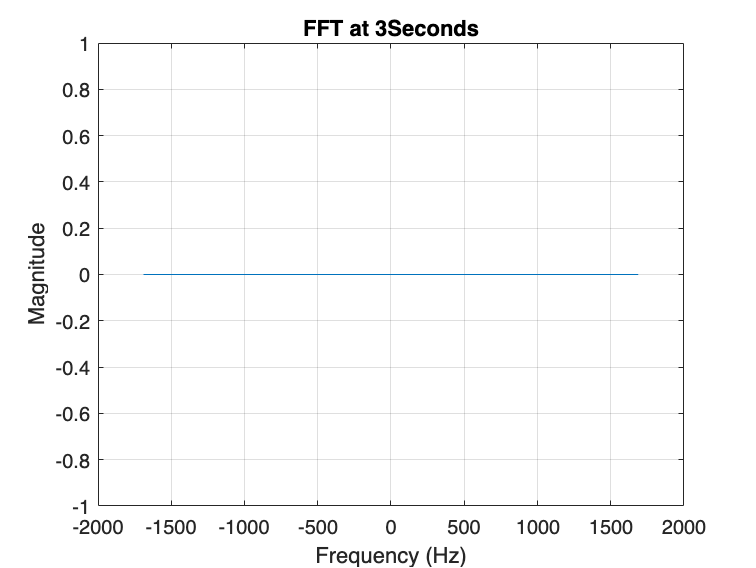

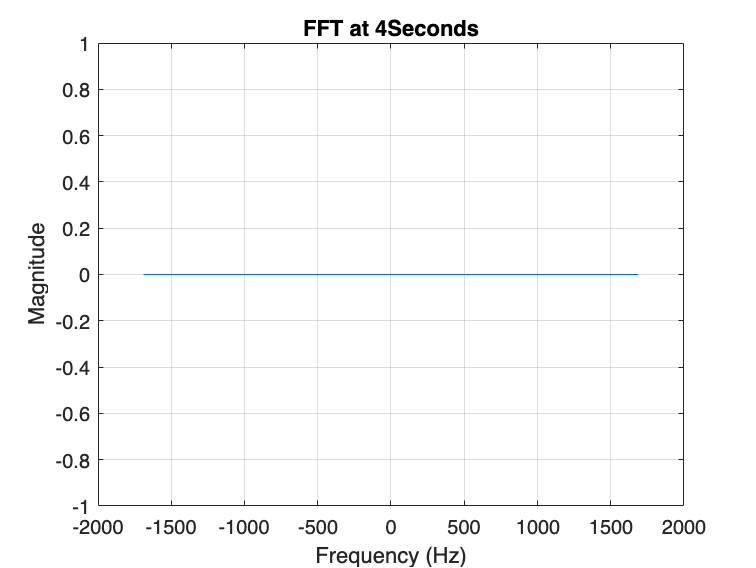

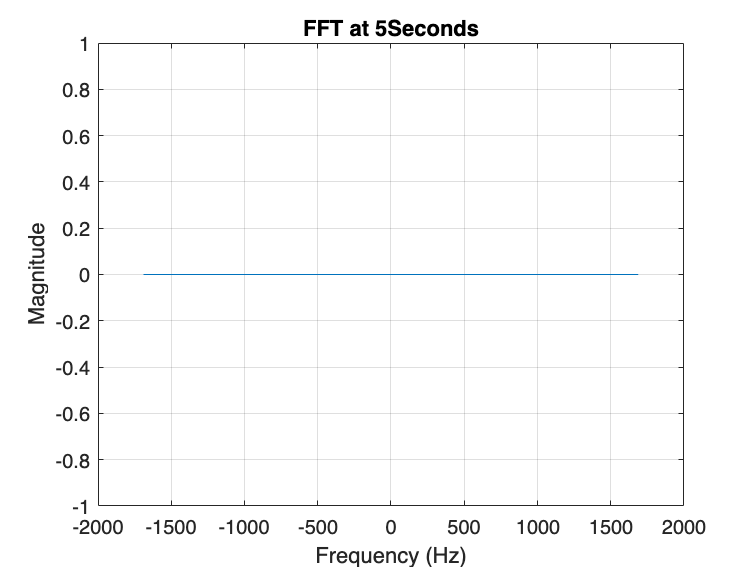

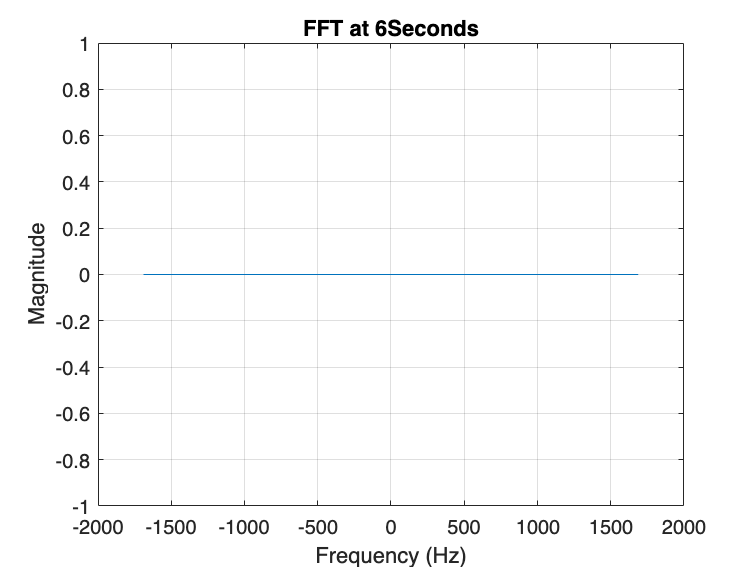

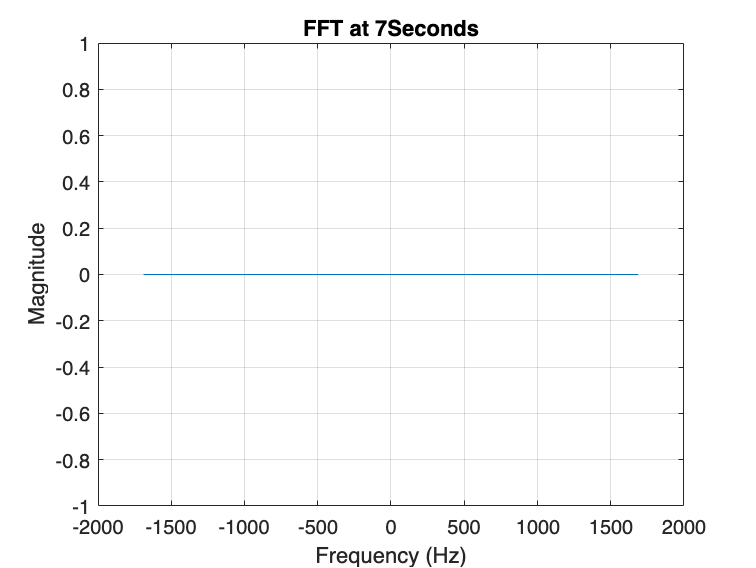

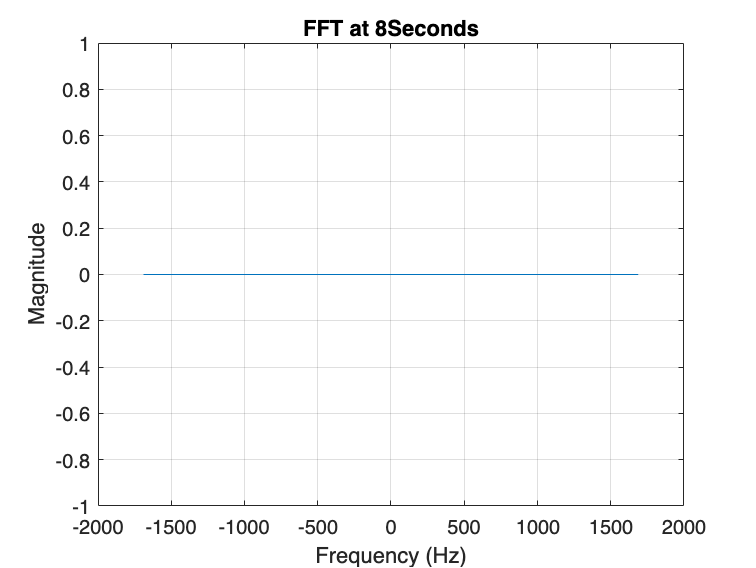

% Define the sampling rate
fs = 580; % Hz
fs = 283; % Hz
fs = 2008; % Hz
fs = 3378; % Hz
% Load the flow rate CSV file
opts = detectImportOptions(filename2);
opts.Delimiter = ",";
data = readtable(filename2,opts);

% Extract the third column (assuming it's the data you want to analyze)
signal = table2cell(data(:, 2));


% Define a function to convert cell elements to numeric values
%convertToNumeric = @(x) str2double(x);

% Use cellfun to apply the conversion function to each element in the cell array
%signal = cellfun(convertToNumeric, signal, 'UniformOutput', false);
signal = cell2mat(signal);

windowsize = 1.0;
N = windowsize*fs; %each window is 1 seconds
windows = floor(length(signal)/(windowsize*fs));
FFTmax = zeros(size(windows));

for i = 1:(windows - 1)

    % Compute the FFT
    %N = length(signal); % Length of the signal
    frequencies = (-N/2:N/2 - 1) * fs / N; % Frequency axis
    fft_result = fft(signal(i*N+1:((i+1)*N))) / N; % Compute FFT and normalize
    fft_shifted_result = fftshift(abs(fft_result));
    [M,I] = max(fft_shifted_result(abs(frequencies)>highpassfreq));
    FFTmax(i) =  (I~=1)*abs(frequencies(I));
    % Plot the magnitude spectrum
    figure;
    plot(frequencies, fft_shifted_result);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude'); 
    title('FFT at ' + string(windowsize*i) + "Seconds");
    grid on;
    
    % Optional: Plot only the positive frequencies (single-sided spectrum)
    % Use this if your signal is real and you want to ignore the negative frequencies
    % positive_frequencies = frequencies(1:N/2+1);
    % plot(positive_frequencies, abs(fft_result(1:N/2+1)));
    % xlabel('Frequency (Hz)');
    % ylabel('Magnitude');
    % title('Single-Sided FFT of the Third Column');
    % grid on;

end

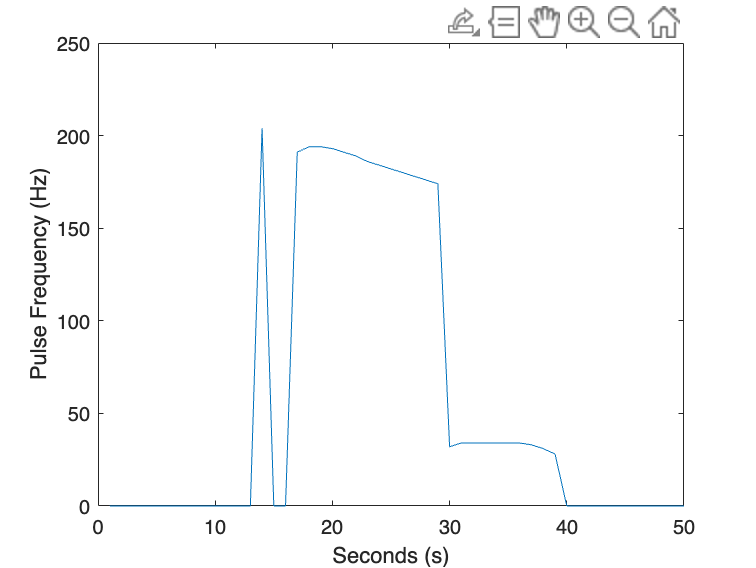

plot(1:windowsize:(windows - 1)*windowsize,FFTmax)
ylabel("Pulse Frequency (Hz)")
xlabel("Seconds (s)")